# Planar R-R DH/mDH setFrameTransform

## Using rigid body tree cell to make a mdh/sdh frame rigid body

Learn to use rigid body tree, the Robotics System Toolbox to understand the difference between equation based MDH/DH parameterization, such that the robotics community using URDF, has it's own single rigid body/single joint in body framework, such that the collision/mass/inertia is embedded on the "linked joint rigid body"

### Purpose

Pre-assign a circular path trajectory in work space, and by doing so the angular velocity is mostly constant for the joint space, and wish to make the angular velocity of the joints as smooth and continuous as possible, where it will be inverse kinematics calculated.

A starting point on the radius that is pre-assigned, and it does not need to be on the circular trajectory at first, and thus it need to move onto the circle, tracking and moving towards the path as "pre-assigned time". Thus turning it to be a continuous "error tracking" problem.

### Challenge

In this case, once the circular path "trajectory error tracking" is established, we will move on to use the Dynamics equation, as well as the assigned gravity/inertia/center of mass to find the calculated torque that is instantaneously "monitored" along the "tracking trajectory". 

It would be physically observed that there is a constant torque during the "tracked" with minimum error moving constant angular velocity for joint movement, or only a small "torque" variation during "acceleration/deceleration", but a more significant "torque" when "acceleration from starting point" as the workspace is initially not on the circular path and exhibits "tracing" error for trying to "catch up" onto the "pre-designed" circular workspace path, and such that the "inverse kinematics" should quickly calculate the needed torque to compensate to such a mismatch..

#### Design steps:

- setup the rigidRobotTree. Make sure the URDF style robot is setFrameTransform fixed as the R-R planar manipulator, and use both MDH/DH table like framework and can translate to the associated values, so in MDH there are the $x_{1mdh}, x_{2mdh}, x_{3mdh}$ frames, and the DH has the $x_{1dh}, x_{2dh}$ frames. Not to be confused with the joint_1, joint_2 frames of the rigid body tree. As they are the robot rigidBodyTree frames, that helps us to transform to the $x_{1mdh}, x_{2mdh}, x_{3mdh}$ and $x_{1dh}, x_{2dh}$, when needed to compare to theoretical values.

- once the joint_1, joint_2 along with the body_1, body_2 that is assigned properly, one would use the forward kinematics/inverse kinematics function provided from the robotic system toolbox to design and find the "reference workspace trajectory" and the "reference joint space trajectory" both for all the "position/velocity/acceleration" as they are essential for "error tracking". There will be: first a                  open loop operation, then second a "state feedback" close loop operation. Just to feel the "tracking error" being able to become smaller. The former "open loop" should be the basis of collecting all the simulated values. Where first one assign all necessary parameters, such as J_1, J_2, CM_1, CM_2, and all kinematics L_1, L_2 values. With home position (\theta_1, \theta_2) that makes the EOF not on the circular workspace trajectory path. Then this will make the manipulator run with always an "offset" to the designed trajectory. Though inverse kinematics and inverse dynamics will offer a "not-mismatched" perfect trajectory. And since there is no disturbance (no sudden change in inertial/mass/center of mass) in the dynamic sense. Only the "offset from initial condition by home position" will survive all through the trajectory non-tracking. However the objective in this step is to make sure all values are presented and be able to show "visualization", hopefully with full 3D "mismatch".

- By using the robotics system toolbox, and with "feedback" controller designed, there should be some pid like movement, where the controller will try to "match" the trajectory. This should show the "dynamic torque" deviation from the previously "non-feedback/always mismatch" condition. And to record all the values of joint space: angular position/angular velocity/angular acceleration such that they differ from the previous "pre-designed" value. In this case showing "non-adaptive state feedback" on position/velocity (not to feedback force?)

clc;
% clear ??
close all;


## Practice se3 objects with transforms matrix manipulation

make and show frames with joint to parent idea {i-1} -> {i}, and child to joint idea {i+1} -> {i}

Recall that joint frame is having the same body frame location, only that joint frame with joint movement is body frame orientation.

world -> parent transform (joint frame) ->joint motion (body frame) -> collision local pose (collision geometry)

% using standard frame with original location and standard orientation,
% plot on base figure

eul = [pi/3 pi/2 2]   % euler angles (roll/pitch/yaw or x-/y-/z-) at (0,0,0)

eul =     1.0472    1.5708    2.0000


xyz = [-1.0 +3 pi]   % world location, at (0,0,0)

xyz =    -1.0000    3.0000    3.1416



eul2tform(eul)  % check transformation and representations

ans =     0.0000    0.8150    0.5794         0
    0.0000    0.5794   -0.8150         0
   -1.0000    0.0000   -0.0000         0
         0         0         0    1.0000


eul2rotm(eul)   % check rotational matrix representations 

ans =     0.0000    0.8150    0.5794
    0.0000    0.5794   -0.8150
   -1.0000    0.0000   -0.0000


eul2quat(eul)   % quaternion representation. remember quaternion is so3

ans =     0.6284    0.3243    0.6284   -0.3243



trvec2tform(xyz)    % translation vector to homogeneous transformation matrix

ans =     1.0000         0         0   -1.0000
         0    1.0000         0    3.0000
         0         0    1.0000    3.1416
         0         0         0    1.0000



tt = se3(eul2rotm(eul), xyz)    % a general se3 object as frame!!!

tt = se3
    0.0000    0.8150    0.5794   -1.0000
    0.0000    0.5794   -0.8150    3.0000
   -1.0000    0.0000   -0.0000    3.1416
         0         0         0    1.0000




plotTransforms(tt);  % base frame no bodies added!!!
hold on;
tt.trvec

ans =    -1.0000    3.0000    3.1416


tt.tform

ans =     0.0000    0.8150    0.5794   -1.0000
    0.0000    0.5794   -0.8150    3.0000
   -1.0000    0.0000   -0.0000    3.1416
         0         0         0    1.0000


tt.rotm

ans =     0.0000    0.8150    0.5794
    0.0000    0.5794   -0.8150
   -1.0000    0.0000   -0.0000



rotm(tt)

ans =     0.0000    0.8150    0.5794
    0.0000    0.5794   -0.8150
   -1.0000    0.0000   -0.0000


tform(tt)

ans =     0.0000    0.8150    0.5794   -1.0000
    0.0000    0.5794   -0.8150    3.0000
   -1.0000    0.0000   -0.0000    3.1416
         0         0         0    1.0000


trvec(tt)

ans =    -1.0000    3.0000    3.1416



% plot tt frame along with base station for reference
base_frame = se3    % default base station

base_frame = se3
     1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


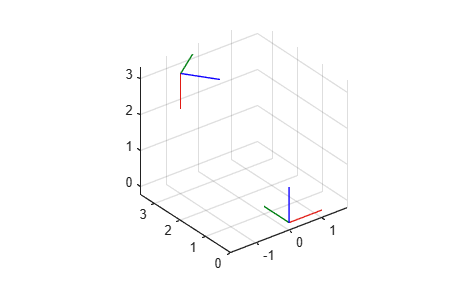

plotTransforms(base_frame)  % showing two frames in same figure.
hold off;

% end of demonstration for arbitrary frame assignment

### Rigid Body tree creation based on se3(s)

### 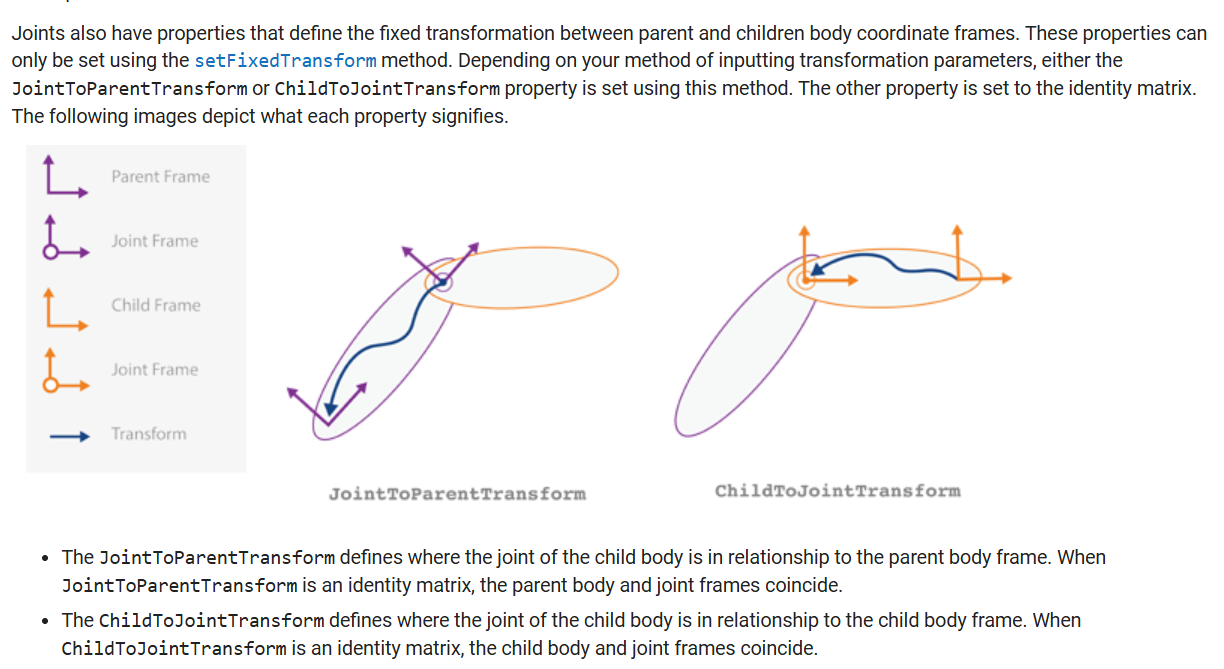

## Drawing joint frames towards bodies (with mdh in mind) as default

make and show different base frames with "joint to parent" idea {i-1} -> {i}, then later attach these transforms to the associated joint object with setTransform command. The frames now are "with home position in mind", and also "following dh/mdh table" convention (so to later use mdh/dh table importation).

this is not the same with direct urdf import.  

### World frame is base frame

clear ans h quat tt

% plotTransforms(base_frame);  % plot base frame
% hold on;


#### Making the robot tree object

please refer to: [rigid body tree model, with rigidBodyTree function](https://www.mathworks.com/help/robotics/ug/rigid-body-tree-robot-model.html)

robot = rigidBodyTree;  % calling the rigid body tree == robot

% In robotics system toolbox user guide (2026a) it was
% robot = rigidBodyTree("DataFormat", "column");  % maybe using column based
% input [x y z]'

In the most important scene, one has to start mentally trace all the frames that are associated to all the different "bodies".

The default is to define the base frames, as in the "world frame" as rigid body tree base, this is default translation = [0 0 0], rotation  = I_3, and designated frame {0} at Origin. **0th frame, refer to: **[rigid body tree model, with rigidBodyTree function](https://www.mathworks.com/help/robotics/ug/rigid-body-tree-robot-model.html), and notice it cannot be modified.

base = robot.Base

base =   rigidBody with properties:

          Name: 'base'
      Children: {1×0 cell}
       Visuals: {}
    Collisions: {}
    FrameNames: {'base'}


#### 1st frame, 1st body, and 1st joint in one class

I'd like a round cylinder with fixed joint (just a round stand, this will be frame {1} for the plate body) later so to elevate the next joint (the next joint/link called arm1, with joint frame/body frame of next arm (child of current plate) will be frame {2}). Coincidentally, this frame {1} will be exactly located at frame {0}.

**Note all rigid body class please refer to: ** [rigid body function, notice all the frame/mass/inertia settings](https://www.mathworks.com/help/robotics/ref/rigidbody.html)

%% moving to next frame manually...
plateBase = rigidBody("plate_base");    % note this is the first body, not named as "base", but "plate_base" 

Now we'd like to add an collision object to make it easier for visualization, but notice we will still be "collision free" from default operation.


collBase = collisionCylinder(3, 3); % radius, length 

% need to offset the collision body up 1.5 to make the surface at x-y plane
collBase.Pose = trvec2tform([0 0 3/2])

collBase =   collisionCylinder with properties:

    Radius: 3
    Length: 3
      Pose: [4×4 double]


The above collision object is added to the rigid body "plateBase" for visualization.

addCollision(plateBase,collBase)

Then the next part is to add a joint by rigidBodyJoint function, that is attached to the rigid body.

plateJoint = rigidBodyJoint("plate_joint","revolute");
plateBase.Joint = plateJoint;       % notice it must be attached directly to the body, by replacing default.

This joint is defined with it's type, and as associated with a joint frame using setFixFrame function. Please refer to: [please note the "moving availability" part](https://www.mathworks.com/help/robotics/ref/rigidbodyjoint.html)

This body with joint now is "linked together", and it must be added to the "robot" now. Notice there is no** frame association **to any of the body and joint, as the joint frame is main "frame" acting as the "body frame" but all is "default".

The next part is to set the joint/body frame to the rigid body, through the rigid body joint. The function is setFixedTransoform: [recall the joint to parent is mdh standard ](https://www.mathworks.com/help/robotics/ref/rigidbodyjoint.setfixedtransform.html#bvet6i2)

setFixedTransform(plateJoint,base_frame)

This makes the rigid body ready with 1. joint type and 2. joint location, also with a visualization of cylinder. Now we can add it to the robot (rigid Body Tree)

addBody(robot,plateBase,'base')

Due to the need to "personally see the frame assignment from theory" the following frames are show here.

% test on making a new frame to link the top of the plate_base.By DH
% parameter for frame{1}, as mdh frame setting for 1st planar r-r robot
% (not coinciding with frame{0})
plotTransforms(base_frame)  % base_frame = f{0}, is f0 also in code
hold on;

f1 = se3(rotz(30));     % rotating plate frame, rotated 30 degrees, body "plateBase" cylinder rotated. f{1}

plotTransforms(f1)

eul = [0 -pi/2 0];   % rotate about x-axis at -90 degrees, remember euler is z-y-x default
xyz = [0 0 3];      % move along z-axis +1.5 meter
f2 = se3(eul,"eul",xyz);   % change euler representation into quaternion representation. Joint non-moving frame for lower arm body "body1"

f2b = f2*se3(rotz(60))

f2b = se3
    0.0000   -0.0000   -1.0000         0
    0.8660    0.5000         0         0
    0.5000   -0.8660    0.0000    3.0000
         0         0         0    1.0000


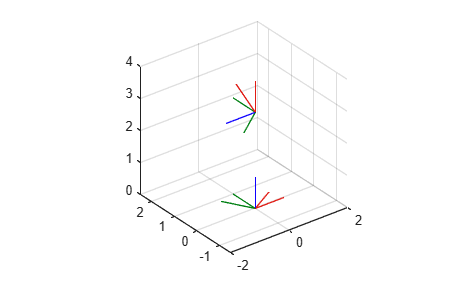


plotTransforms(f2)
plotTransforms(f2b)

hold off;

Now to compare the how the robot visualization is added to another figure 2.

The following two figures, are deliberately used to store the "show robot" for 1. the frame, 2. the collision illustration

2nd frame, 2nd body, and 2nd joint 

This is going to be a box to make home position 45 degree to the rotated z-axis as like mdh setup. So now the joint axis is at (0,0,3) of the original wold/base frame

body1 = rigidBody('lower_arm');

coll1 = collisionBox(3, 0.5, 0.5)  % box of (10 cm by 10 cm by 1.5 m)

coll1 =   collisionBox with properties:

       X: 3
       Y: 0.5000
       Z: 0.5000
    Pose: [4×4 double]


coll1.Pose = trvec2tform([3/2 0 0]);

addCollision(body1, coll1)

jnt1 = rigidBodyJoint('jnt1','revolute');
setFixedTransform(jnt1,f2)  % set fixed frame before adding body to robot tree
% this ensures that the body/joint frame fixed relative to the parent
% frame.
body1.Joint = jnt1;

addBody(robot,body1,plateBase.Name)

Showing updated figures, need a home_configuration

showdetails(robot)  % making sure the detail of the robot connections

--------------------
Robot: (2 bodies)

 Idx         Body Name         Joint Name         Joint Type         Parent Name(Idx)   Children Name(s)
 ---         ---------         ----------         ----------         ----------------   ----------------
   1        plate_base        plate_joint           revolute                  base(0)   lower_arm(2)  
   2         lower_arm               jnt1           revolute            plate_base(1)   
--------------------



config = homeConfiguration(robot)   % handle to make sure configurations

config = 1×2 struct array with fields:
    JointName
    JointPosition


To setup home configuration of one arm

% for theta = linspace(-pi/4, pi/4, 100)
% 
%     config.JointPosition = theta;
% 
%     show(robot, config, ...
%         'Collisions','on', ...
%         'PreservePlot',false);
% 
%     axis equal
%     view(3)
%     drawnow
% 
% end


## making a video

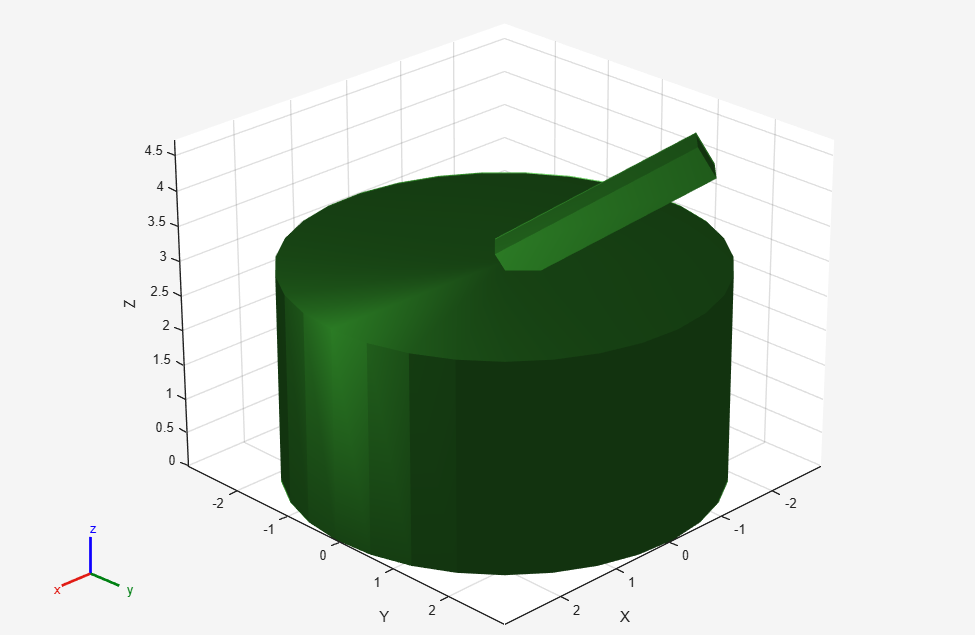

v = VideoWriter("robot_arm_motion.mp4","MPEG-4");
v.FrameRate = 30;
open(v);

figure(1)
clf

q1_0 = pi/4;
q2_0 = pi/3;

% config(1).JointPosition = q1_0;
% config(2).JointPosition = q2_0;
% 
% show(robot,config,"Collisions","on")
% 
% axis equal
% view(135,25)

for theta = linspace(0, -pi/2, 120)

    config(1).JointPosition = q1_0 + theta;
    config(2).JointPosition = q2_0 + theta;

    show(robot,config,"Collisions","on","PreservePlot",false)
    
    axis equal
    view(135,25)

    drawnow limitrate

    frame = getframe(gcf);
    writeVideo(v,frame);

end

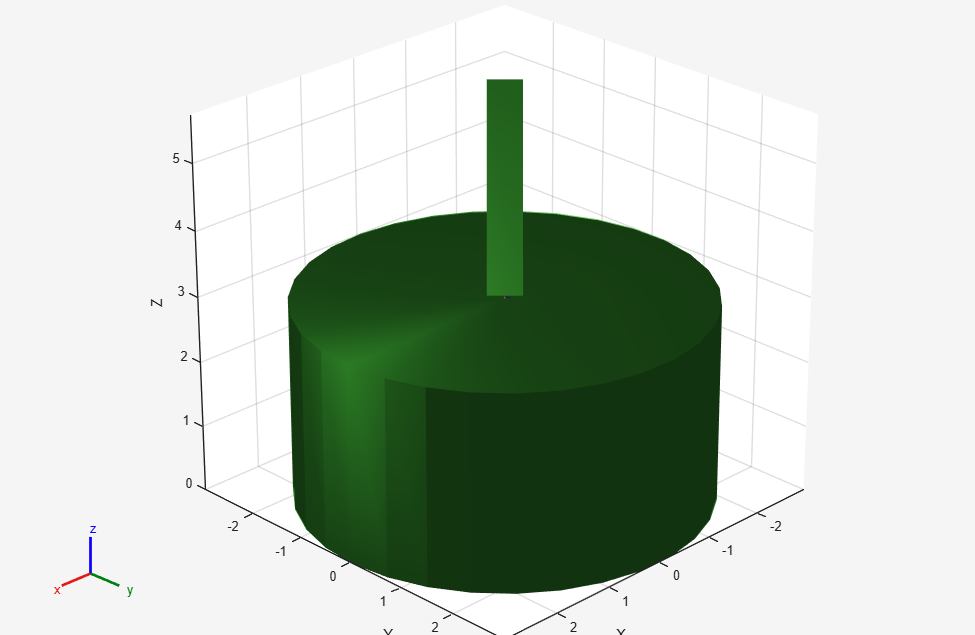


close(v)

rotate3d on


% tt = getTransform(robot,config,"plate_base")
% rad2deg(tform2eul(tt))
% tt = getTransform(robot,config,"lower_arm","plate_base")
% rad2deg(tform2eul(tt))
